# The Friedkin-Johnsen model

The discrete-time model with prejudices, and the only one of the four with substantial empirical validation.

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

NDS opinion-dynamics library added to the path.
Project root: /Users/llp/Desktop/NDS_Project


## Reproducing Figure 6 of the tutorial

The influence matrix is the empirically identified one of Friedkin & Johnsen (1999), reprinted as Eq. (24). Three susceptibility matrices give the three panels. Agent 3 is stubborn in every case, since row 3 of W is e_3.

[net, u, x0] = make_example_fj4();
disp(net.W)

    0.2200    0.1200    0.3600    0.3000
    0.1470    0.2150    0.3440    0.2940
         0         0    1.0000         0
    0.0900    0.1780    0.4460    0.2860




presets = { ...
    fj_lambda(net, 'identity'),         '(a) \Lambda = I: consensus'; ...
    fj_lambda(net, 'classic'),          '(b) \Lambda = I - diag(W): cleavage'; ...
    fj_lambda(net, 'stubborn', [2 3]),  '(c) \Lambda = diag(1,0,0,1)'};

figure;
tl = tiledlayout(3, 1);
for k = 1:3
    r = sim_friedkin_johnsen(net, presets{k, 1}, u, x0, 12);
    plot_opinions(r, 'Axes', nexttile(tl), 'Prejudice', u, ...
        'Title', presets{k, 2}, 'Legend', k == 1);
    fprintf('%-34s limit = %s\n', presets{k, 2}, mat2str(round(r.xinf.', 4)));
end

(a) \Lambda = I: consensus         limit = [0.6 0.6 0.6 0.6]
(b) \Lambda = I - diag(W): cleavage limit = [0.1666 0.3521 0.6 0.6692]
(c) \Lambda = diag(1,0,0,1)        limit = [0.39 -0.2 0.6 0.3741]


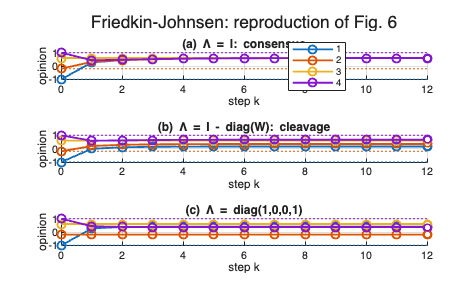

title(tl, 'Friedkin-Johnsen: reproduction of Fig. 6');

## Reading the three panels

(a) Lambda = I removes the anchoring term entirely, so the model IS French-DeGroot and the group converges on agent 3's opinion. (b) Friedkin's own coupling lambda_i = 1 - w_ii keeps every agent partly tied to its prejudice. All three free agents move towards agent 3, but a visible cleavage remains -- forever. (c) With agents 2 and 3 both stubborn, agents 1 and 4 settle at distinct but very close opinions strictly between the two anchors.

resB = sim_friedkin_johnsen(net, presets{2,1}, u, x0, 60);
resC = sim_friedkin_johnsen(net, presets{3,1}, u, x0, 60);
fprintf('\n(b) residual spread : %.4f\n', max(resB.xinf) - min(resB.xinf));


(b) residual spread : 0.5026


fprintf('(c) agents 1 and 4  : %.4f and %.4f (difference %.4f)\n', ...
    resC.xinf(1), resC.xinf(4), abs(resC.xinf(1) - resC.xinf(4)));

(c) agents 1 and 4  : 0.3900 and 0.3741 (difference 0.0159)


## The total-influence matrix V

x(inf) = V u with V = (I - Lambda W)^{-1} (I - Lambda), and V is ROW-STOCHASTIC. The rank of the limit operator is what separates consensus from cleavage:

out = fj_matrices(net.W, presets{2, 1});
disp(round(out.V, 4))

    0.2794    0.0450    0.5514    0.1242
    0.0471    0.2783    0.5492    0.1254
         0         0    1.0000         0
    0.0301    0.0481    0.5324    0.3894



fprintf('row-stochastic : %d\n', out.isRowStochasticV);

row-stochastic : 1


fprintf('rho(Lambda W)  : %.6f\n', out.rho);

rho(Lambda W)  : 0.453818


fprintf('rank(V)        : %d of %d\n', out.rankV, net.n);

rank(V)        : 4 of 4


fprintf('singular values: %s\n', mat2str(round(out.svdV.', 4)));

singular values: [1.4147 0.3533 0.2374 0.2291]


## Exact analytic checks

Two 2x2 cases from Bullo, Lectures on Network Systems, exercise E5.24(v), with exactly known answers. They make the rank point with no numerics at all.

W2 = [0.5 0.5; 0.5 0.5];
o1 = fj_matrices(W2, [0.5; 1]);
o2 = fj_matrices(W2, [0.25; 0.75]);

fprintf('\nLambda = diag(1/2, 1)   -> V = %s, rank %d  (consensus at agent 1''s prejudice)\n', ...
    mat2str(o1.V), o1.rankV);


Lambda = diag(1/2, 1)   -> V = [1 0;1 0], rank 1  (consensus at agent 1's prejudice)


fprintf('Lambda = diag(1/4, 3/4) -> V = %s, rank %d  (persistent disagreement)\n', ...
    mat2str(round(o2.V, 6)), o2.rankV);

Lambda = diag(1/4, 3/4) -> V = [0.9375 0.0625;0.5625 0.4375], rank 2  (persistent disagreement)


## Influence centrality and PageRank

Friedkin's influence centrality c = V'*1/n generalises social power to the non-consensus case. With Lambda = alpha*I it converges to French's social power as alpha -> 1 (Lemma 24), and it reproduces PageRank with alpha = 1 - m and uniform prejudice -- teleportation and prejudice are the same mathematical device.

ring = make_ring(7, 'SelfWeight', 0.25);
p = social_power(ring);

fprintf('\n alpha    ||c_alpha - p||_inf\n');


 alpha    ||c_alpha - p||_inf


for a = [0.5 0.9 0.99 0.999]
    c = fj_matrices(ring.W, a, 'Warn', false).c;
    fprintf('%6.3f    %.3e\n', a, norm(c - p, Inf));
end

 0.500    8.327e-17
 0.900    1.110e-16
 0.990    3.053e-16
 0.999    6.384e-15



m = 0.15;                                   % Google's damping
cPR = fj_matrices(ring.W, 1 - m, 'Warn', false).c;
fprintf('\nPageRank (m = 0.15) = %s\n', mat2str(round(cPR.', 4)));


PageRank (m = 0.15) = [0.1429 0.1429 0.1429 0.1429 0.1429 0.1429 0.1429]


## Stubborn-agent placement

Which agent should be anchored to move the group most? Make each agent totally stubborn in turn and measure the shift in the group mean.

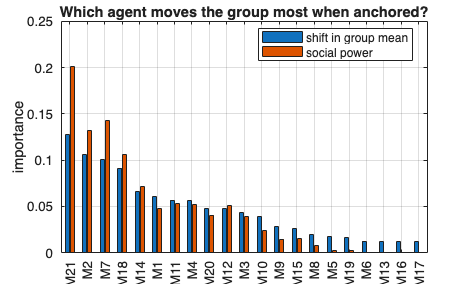

kr = load_krackhardt();
lambdaBase = 0.8 * ones(kr.n, 1);
uBase = zeros(kr.n, 1);

baseline = fj_matrices(kr.W, lambdaBase, 'Warn', false).V * uBase;
shift = zeros(kr.n, 1);
for i = 1:kr.n
    lam = lambdaBase; lam(i) = 0;
    uu = uBase;       uu(i) = 1;            % the anchored agent pushes towards 1
    xi = fj_matrices(kr.W, lam, 'Warn', false).V * uu;
    shift(i) = mean(xi) - mean(baseline);
end

pk = social_power(kr);
figure;
plot_influence_bars([shift, pk], 'Labels', kr.labels, 'Normalize', true, ...
    'SeriesNames', {'shift in group mean', 'social power'}, 'Sort', 'descend', ...
    'Title', 'Which agent moves the group most when anchored?');


fprintf('\ncorrelation(shift, social power) = %.4f\n', pearson_correlation(shift, pk));


correlation(shift, social power) = 0.9828


[~, best] = max(shift);
fprintf('most effective anchor: manager %d (social power rank %d)\n', ...
    best, find(sort(pk, 'descend') == pk(best), 1));

most effective anchor: manager 21 (social power rank 1)
